## Solve LQR for Optimal Feedback and V

THIS FILE IS MAINLY USED TO GENERATE PARTS OF THE REPORT FOR DR K

IT IS GENERALLY SLOWER THAN THE main.mlx file

clear all

linear_system = false; % This switches between the linear and nonlinear systems

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%{
- Linear System LQR
We solve this system to find the optimal V_star and Mu_star
Then we feed optimal control input u = Mu_star into the algorithm
to estimate
%}
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

k = 1;
A = [0 1; -k 0]; 
B = [0; 1;];

Q = eye(2);
R = 1;
[K,S] = lqr(A,B,Q,R);

sqrtNum_centers_vector = [5:2:11];

sqrtNum_centers = max(sqrtNum_centers_vector);
counter=0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This big loop is used to calculate the error_inf vs N
% for kk = max(sqrtNum_centers_vector):-2:4
for kk = min(sqrtNum_centers_vector):2:max(sqrtNum_centers_vector)
    sqrtNum_centers = kk;

    clearvars -except sqrtNum_centers sqrtNum_centers_vector...
        K S V_star Mu_star Q R x0 data L_inf_error L_2_error kk centers numCenters...
        linear_system counter cond_num_save
    for covar_counter = 1:4
        covar = 120*covar_counter/4
%     covar = max(sqrtNum_centers_vector)^2;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

covar = 30

covar = 60

covar = 90

covar = 120

covar = 30

covar = 60

covar = 90

covar = 120

covar = 30

covar = 60

covar = 90

covar = 120

covar = 30

covar = 60

covar = 90

covar = 120

## Pick Centers and Form Phi Matrix

The centers are picked uniformly in a square mesh.

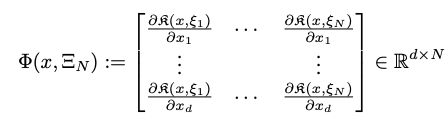

    % sqrtNum_centers is the square root of the number of centers needed in a
    % 2D mesh. The actual number of centers will be the square of this number.

    [centers,numCenters] = form_uniform_centers(sqrtNum_centers,"logspace");
    % centers = [centers [1/3; -1] [-1/3; -1] [1/3; 1] [-1/3; 1] ]
    % numCenters = numCenters+4
%     centers = [centers [-1; 1/3] ]
%     numCenters = numCenters+5


    % Remove the zero center (the fixed point)% Pickout the zero center if its one
    % of the centers and remove it% Pickout the zero center if its one
    % of the centers and remove it
    % centers(:,all(centers==0))=[]; 
    % numCenters=numCenters-1;
    % centers = [centers(2,:); centers(1,:)]


    % % TODO: Turn this into a function
    % Extract a subset of centers from previous centers. Works on odd
    % number of centers.
    % For this to work, we need to reverse the order of the big loop.
    % if kk>1
    %
    %     centers_x = centers(1,:);
    %     centers_x = reshape(centers_x,sqrtNum_centers,sqrtNum_centers);
    %     centers_y = centers(2,:);
    %     centers_y = reshape(centers_y,sqrtNum_centers,sqrtNum_centers);
    %
    %
    %     sqrtNum_centers = ((sqrtNum_centers-1)/2)+1; % New number of centers
    %     numCenters = sqrtNum_centers^2;
    %
    %     centers_x = centers_x(1:2:end,1:2:end);
    %     centers_x = reshape(centers_x,1,numCenters);
    %
    %     centers_y = centers_y(1:2:end,1:2:end);
    %     centers_y = reshape(centers_y,1,numCenters);
    %     centers = [centers_x; centers_y];
    %
    % end



## Quadrature Approximation

#### LHS is defined as: $
\left [\int_\Omega \Phi^T(x,\Xi_N)\psi(x)\psi(x)^T\Phi(x,\Xi_N) dx \right ] \alpha
$

#### RHS is defined as: $
\int_\Omega \Phi^T(x,\Xi_N) \psi(x) b(x)
$ where b(x) is the cost function $J(x,u) = x^TRx + u^TQu$

    % Initialize
    minCond = 10^20;

    LHS = zeros(numCenters,numCenters);
    RHS = zeros(numCenters,1);
    n_quad = numCenters; % Number of quadrature points depends on the number of centers, actual number of quad points is n_quad^2
    %     if n_quad<50 % Set a minimum number of quadrature points
    %         n_quad = 50;
    %     end

    % Define Quadrature Integration Points
    % Create a mesh of evaluation points for x
    x_eval = [linspace(-1,1,n_quad)]; %
    y_eval = linspace(-1,1,n_quad);
    [X_eval,Y_eval] = meshgrid(x_eval,y_eval);
    p = [X_eval(:) Y_eval(:)]; % Get a matrix of (x-y) co-ordinates

    % [p,x_eval,y_eval] = createCircularMesh(1,33);

    u_curr_point = zeros(length(p),1);

    for i=1:length(p)
        curr_point = p(i,:)';
        x = curr_point;

        phi_matrix = form_phi_matrix(curr_point,centers,covar);

        if linear_system==true
            u = -K*curr_point;
            spatial_dynamics = calculate_spatial_dynamics(curr_point,u);
        else
            u = -(cos(2*x(1))+2)*x(2);
            spatial_dynamics = nonlinear_dynamics(curr_point,u);
        end

        curr_eval = (phi_matrix'*(spatial_dynamics*spatial_dynamics')*phi_matrix);

        LHS = LHS + curr_eval;
        RHS = RHS + phi_matrix'*spatial_dynamics*(-cost_Func(curr_point,u,Q,R));

    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % CHECK ideal projection solution
    for i=1:numCenters
        for j=1:numCenters
            kerns_gramian(i,j) = kernel(centers(:,i),centers(:,j),covar);
        end
    end

    if linear_system == true
        curr_V_star = centers'*S*centers;
        curr_V_star = diag(curr_V_star);
    else
        curr_V_star= 0.5*centers(1,:)'.^2 + centers(2,:)'.^2;
    end

    beta = kerns_gramian\curr_V_star;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % Eliminate V at zero using lagrange multipliers
    kerns_centers_zero = zeros(numCenters,1);
    for j=1:numCenters
        kerns_centers_zero(j,:) = kernel(0,centers(:,j),covar);
    end

    % Applying Lagrange multipliers method to enforce BC V(0)=0
    LHS_new = [LHS         kerns_centers_zero;
        kerns_centers_zero' zeros(1,1)];
    RHS_new = [RHS; 0];

   % [~,sigma,~] = svd(LHS);
   %  sigma=diag(sigma)'
   %  semilogy(sigma)

% LHS_new=LHS;
% RHS_new=RHS;    
%     [~,sigma,~] = svd(LHS_new);
%     sigma=diag(sigma)'
%     semilogy(sigma)

    alpha_new = LHS_new\RHS_new;
    alpha_new = alpha_new(1:end-1);

    alpha_old = LHS\RHS;

    cond(LHS_new)

ans = 6.2440e+05

ans = 3.6349e+05

ans = 2.6405e+05

ans = 2.1747e+05

ans = 1.2828e+07

ans = 6.7487e+06

ans = 4.5445e+06

ans = 3.5314e+06

ans = 9.8343e+07

ans = 5.5235e+07

ans = 3.4072e+07

ans = 2.6477e+07

ans = 5.1054e+08

ans = 3.2637e+08

ans = 2.3738e+08

ans = 1.7636e+08


    cond_num_save(counter+1,covar_counter) =  cond(LHS_new)

cond_num_save = 6.2440e+05

cond_num_save = 1.0e+05 *

    6.2440    3.6349


cond_num_save = 1.0e+05 *

    6.2440    3.6349    2.6405


cond_num_save = 1.0e+05 *

    6.2440    3.6349    2.6405    2.1747


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828         0         0         0


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828    0.6749         0         0


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828    0.6749    0.4545         0


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828    0.6749    0.4545    0.3531


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828    0.6749    0.4545    0.3531
    9.8343         0         0         0


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828    0.6749    0.4545    0.3531
    9.8343    5.5235         0         0


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828    0.6749    0.4545    0.3531
    9.8343    5.5235    3.4072         0


cond_num_save = 1.0e+07 *

    0.0624    0.0363    0.0264    0.0217
    1.2828    0.6749    0.4545    0.3531
    9.8343    5.5235    3.4072    2.6477


cond_num_save = 1.0e+08 *

    0.0062    0.0036    0.0026    0.0022
    0.1283    0.0675    0.0454    0.0353
    0.9834    0.5523    0.3407    0.2648
    5.1054         0         0         0


cond_num_save = 1.0e+08 *

    0.0062    0.0036    0.0026    0.0022
    0.1283    0.0675    0.0454    0.0353
    0.9834    0.5523    0.3407    0.2648
    5.1054    3.2637         0         0


cond_num_save = 1.0e+08 *

    0.0062    0.0036    0.0026    0.0022
    0.1283    0.0675    0.0454    0.0353
    0.9834    0.5523    0.3407    0.2648
    5.1054    3.2637    2.3738         0


cond_num_save = 1.0e+08 *

    0.0062    0.0036    0.0026    0.0022
    0.1283    0.0675    0.0454    0.0353
    0.9834    0.5523    0.3407    0.2648
    5.1054    3.2637    2.3738    1.7636


    end
    

    assert(cond(LHS_new)<1e10,"CEHCK CONDITION NUMBER") % Set a hard limit on the condition number
    % I believe that a condition number of 10^10 should give an accuracy of
    % 10^-6, given machine precision of 10^-16

    % covar
    % alpha = LHS\RHS;
    alpha = alpha_new;
    % max(alpha_new-alpha)

## Calculate $V_N$ and $\mu_{i+1}$Estimates

#### 
$$V_N = \sum_{j=1}^N \alpha_j \mathcal{k}_{\xi_j}$$


#### and

#### 
$$\mu_{i+1} =-0\ldotp 5R^{-1} {\underline{g} \left(x\right)}^T \Phi \left(x,\Xi_N \right)\underline{\alpha} \;$$


#### Where N above is the number of centers.

    % Find the next contrl input by iterating
    % Mu = calculateMu_Iteration(x0,R,alpha,centers,covar)
    % Mu_star % Ideal Mu Value from LQR
    % kern_centers = zeros(1,numCenters);
    %
    % for i=1:numCenters
    %     kern_centers(1,i) = kernel(x0,centers(:,i),covar);
    % end

    kern_centers_spatial = zeros(numCenters,length(p));
    for i=1:numCenters
        for j=1:length(p)
            curr_point = p(j,:)';
            kern_centers_spatial(i,j) =  kernel(curr_point,centers(:,i),covar);
        end
    end


    V_n_spatial = kern_centers_spatial'*alpha; % Vn found from alpha as in paper
    V_n_ideal = kern_centers_spatial'*beta;    % Ideal Projection Estimate

    V_star_save = zeros(1,length(p));
    for i=1:length(p)
        curr_point = p(i,:)';
        if linear_system==true
            V_star_save(i) = curr_point'*S*curr_point;
        else
            V_star_save(i) = 0.5*curr_point(1)^2 + curr_point(2)^2;
        end
    end

    if linear_system == true
    
        ind = find(vecnorm(p')>0.75);
            p = p(ind,:);
        V_n_spatial(ind)=0;
        V_star_save(ind)=0;
    end

    

## Plot Errors

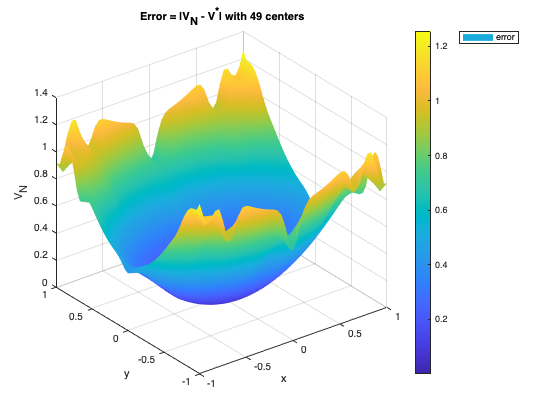

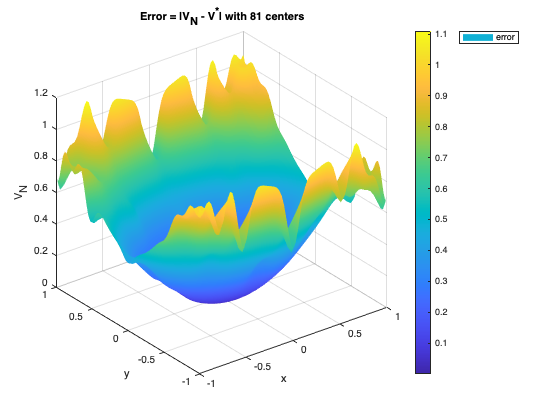

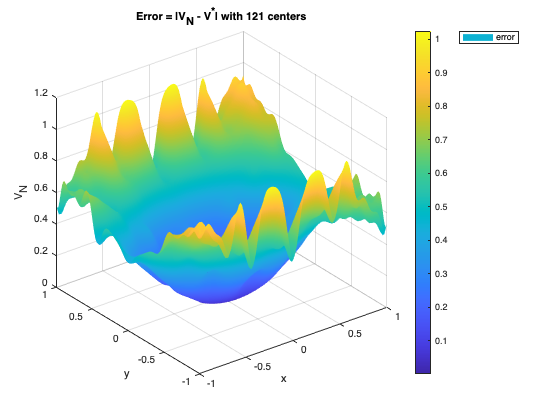


    error = V_n_spatial - V_star_save';

    figure()
    surf(x_eval,y_eval,(abs(reshape(error,n_quad,n_quad))));

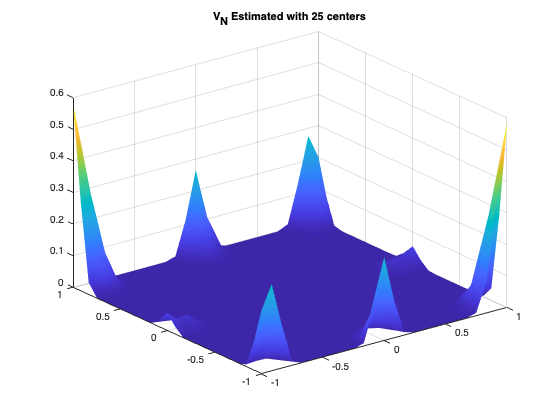

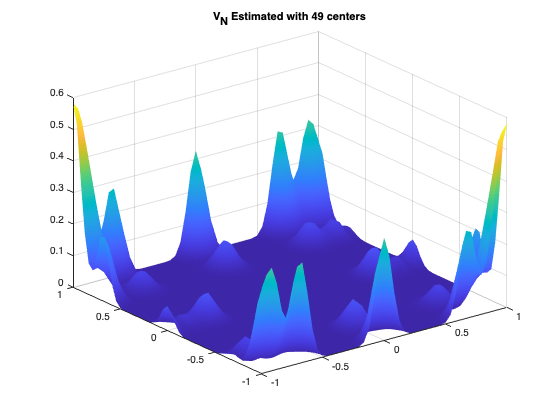

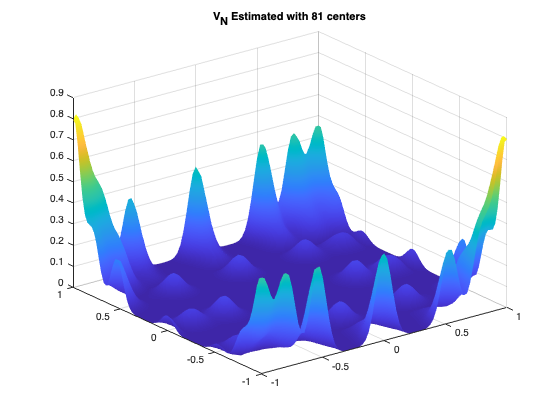

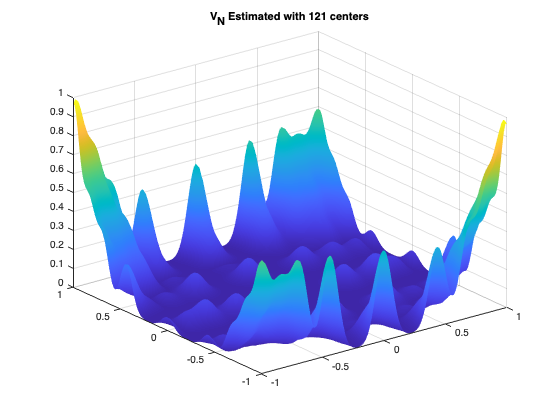

    title(sprintf('Error = |V_N - V^*| with %.0f centers',numCenters))
    shading interp
    xlabel('x'); ylabel('y'); zlabel('V_N'); colorbar; legend('error')

    % Find the centers that happen to be mesh points too and plot them
    % hold on;
    % matchIdx = ismember(p, centers.','rows');
    % colNums = find(matchIdx);
    % plot3(p(colNums,1),p(colNums,2),(error(colNums)),'.r','markersize',25)
    % % surfc(x_eval,y_eval,centers)
    
    % hold off;
    figure()
    surf(x_eval,y_eval,(abs(reshape(V_n_spatial,n_quad,n_quad))))

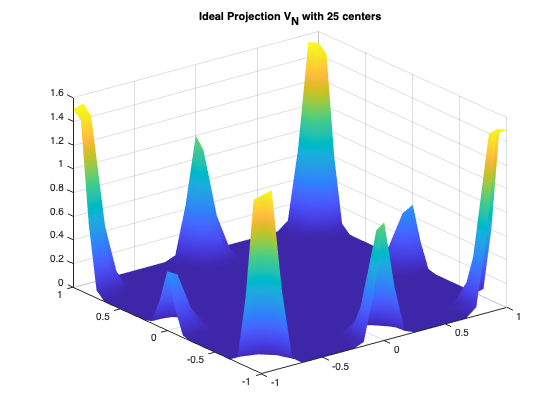

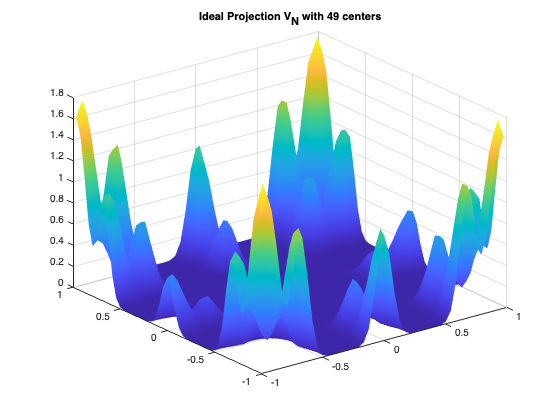

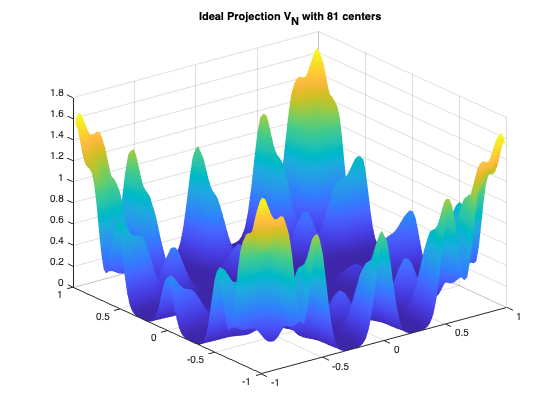

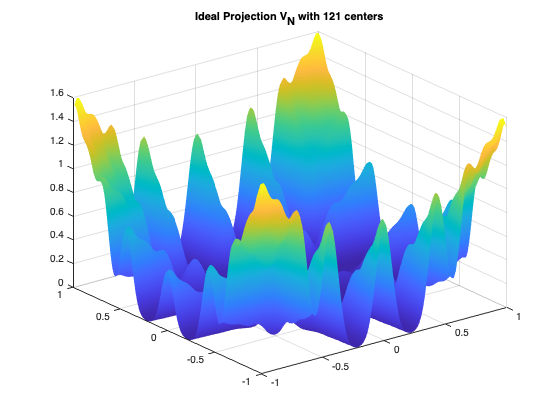

    title(sprintf('V_N Estimated with %.0f centers',numCenters))
    shading interp
    %
    figure()
    surf(x_eval,y_eval,(abs(reshape(V_n_ideal,n_quad,n_quad))));

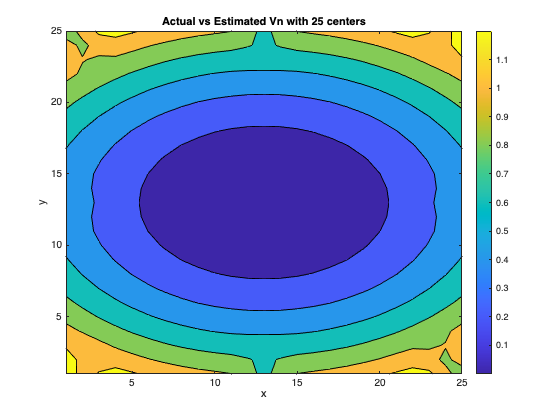

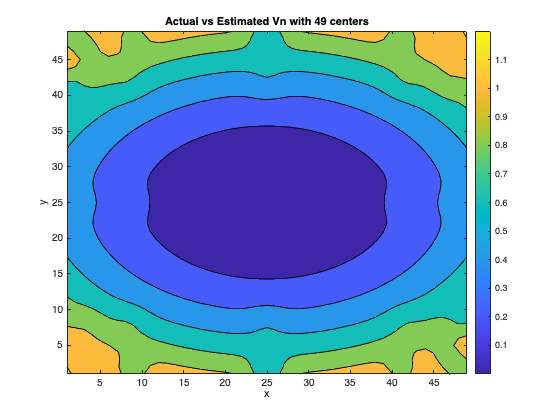

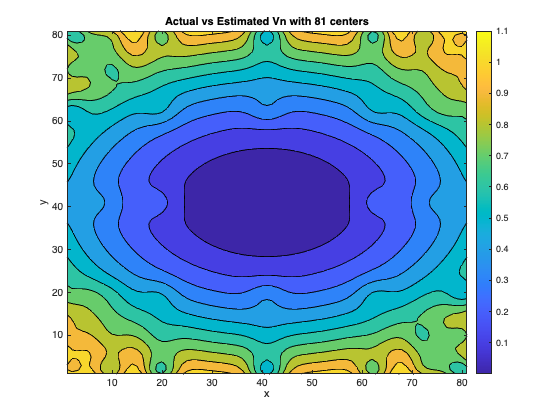

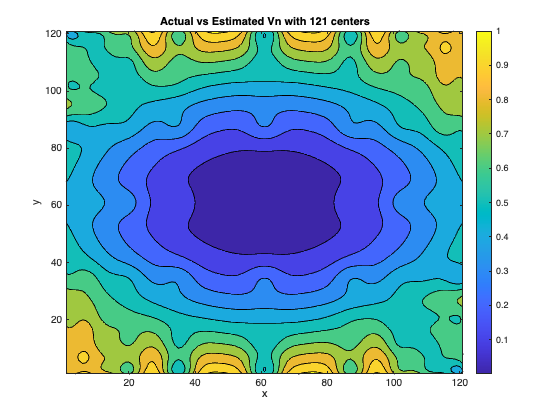

    title(sprintf('Ideal Projection V_N with %.0f centers',numCenters))
    shading interp
    %
    error_ideal = V_star_save'-V_n_spatial;
%     figure()
%     surf(x_eval,y_eval,(abs(reshape(error_ideal,n_quad,n_quad)))); colorbar; shading interp; title('Ideal Projection Error')
    figure()
    contourf(abs(reshape(error_ideal,n_quad,n_quad))); colorbar; title(sprintf('Actual vs Estimated Vn with %.0f centers',numCenters)); xlabel('x')

    ylabel('y')
    % max(abs(error_ideal))

    % figure()
    % surf(x_eval,y_eval,(abs(reshape(V_star_save,n_quad,n_quad))))
    % shading interp

    max(abs(error))

ans = 1.2995

ans = 1.2559

ans = 1.1100

ans = 1.0249

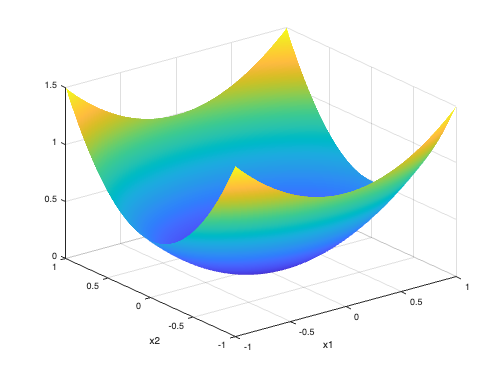


    counter = counter+1;
    L_inf_error(counter) = max(abs(error));
    L_2_error(counter) = norm(abs(error),2);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% End of big loop
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% L_inf_error = flip(L_inf_error) % TODO: Check L2 Error as well

figure()
surf([30 60 90 120],[25 49 81 121],cond_num_save)
ylabel('Number of Centers')
zlabel('Condition Number')
title('Condition Number of LHS with enforced BC')
xlabel('Hyperparameter (Smaller implies wider kernels)')
colorbar

surf(x_eval,y_eval,(abs(reshape(V_star_save,n_quad,n_quad)))); shading interp; xlabel('x1'); ylabel('x2')

## Basis Refinement Error Convergence

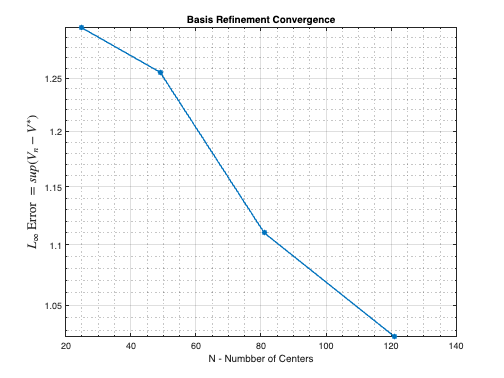

close all

semilogy(sqrtNum_centers_vector.^2,L_inf_error,'*-','LineWidth',1.5);
xlabel('N - Numbber of Centers');
ylabel('$L_{\infty}$ Error $= sup(V_n - V^*)$','Interpreter','latex','FontSize',14)
title('Basis Refinement Convergence'); set(gca, 'XMinorTick','on','XMinorGrid','on'); grid on;

% Plot out v and mu for different numbers of basis

## Plot Kernels at the centers for all x values

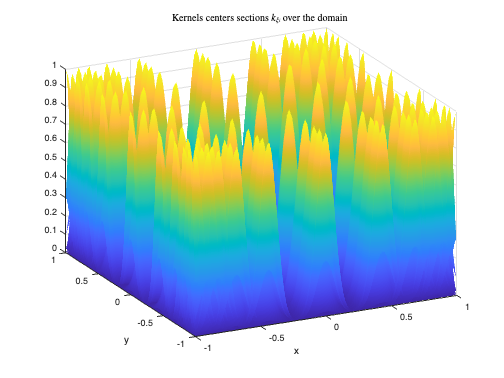

all_kerns = zeros(numCenters,n_quad*n_quad);
counter=0;

for c_counter=1:numCenters % for each center, evaluate k_\xi over the whole domain
    for x_counter=1:n_quad
        for y_counter=1:n_quad
            counter = counter+1;
            all_kerns(c_counter,counter) = kernel([X_eval(x_counter,y_counter);...
                Y_eval(x_counter,y_counter)],centers(:,c_counter),covar);
        end
    end
    counter=0;
end

% Plot a surf plot of all kernels centered at the chosen centers, for all x
% in domain.
for i = 1:numCenters
    surf(x_eval,y_eval,reshape(all_kerns(i,:),n_quad,n_quad)); xlabel('x'), ylabel('y'); hold on
end
title('Kernels centers sections $k_{\xi_i}$ over the domain ','Interpreter','latex')
hold off;

shading interp;
view([-26.386 27.025])


ax3 = gca;


## Plot gradient of kernels

% all_kerns = zeros(numCenters,n_quad*n_quad,2);
% counter=0;
%
% for c_counter=1:numCenters
%     for x_counter=1:n_quad
%         for y_counter=1:n_quad
%             counter = counter+1;
%             curr_point = [X_eval(x_counter,y_counter);Y_eval(x_counter,y_counter)];
%             phi_matrix = form_phi_matrix(curr_point,centers,covar);
%
%             phi_matrix_save(:,:,counter) = phi_matrix;
% %             all_kerns(c_counter,counter,:) = grad_kern_x([X_eval(x_counter,y_counter);Y_eval(x_counter,y_counter)],centers(:,c_counter),covar);
%         end
%     end
%     counter =0;
% end
%
% % Plot a surf plot of all kernels centered at the chosen centers, for all x
% % in domain.
% for i = 1:numCenters
%     surf(x_eval,y_eval,reshape(phi_matrix_save(1,i,:),n_quad,n_quad)); xlabel('x'), ylabel('y'); hold on
%     title('Kernels gradient with respect to x')
% end
% hold off;
% for i = 1:numCenters
%     surf(x_eval,y_eval,reshape(phi_matrix_save(2,i,:),n_quad,n_quad)); xlabel('x'), ylabel('y'); hold on
%     title('Kernels gradient with respect to y')
% end

## Visualize Dynamics

% options = odeset('AbsTol',1e-6);
% [t,X] = ode45(@calculate_dynamics,0:0.25:10,x0,options);
% plot(t,X(:,1))
% plot(t,X(:,2))

## Check Kernels

% x = [1:2]';
% delta = (-0.5:0.001:0.5);
% x_var=x+delta;
% % Covar = eye(size(x,1));
%
% kern = zeros(1,length(delta));
% for i=1:length(delta)
%     kern(i) = kernel(x,x_var(:,i),covar);
% end
% plot(delta,kern)

## Truncated SVD

% alpha = pinv(LHS)*RHS
% % Truncated SVD
% [U,S,V] = svd(LHS);
% truncSVD = @(U,S,V,p) V(:,1:p)*diag(1./diag(S(1:p,1:p)))*U(:,1:p)';
% LHS_truncated_inv = truncSVD(U,S,V,8);
% alpha = LHS_truncated_inv*RHS